tagFamily = "tagCustom48h12";
tagImageFolder = fullfile("C:\Updated_Control_Software\luminos-private\src\Devices\Patterning\Calibration\AprilTags",...
    tagFamily);
imdsTags = imageDatastore(tagImageFolder);

tagArrangement = [5,4];
calibPattern = helperGenerateAprilTagPattern(imdsTags,tagArrangement,tagFamily);

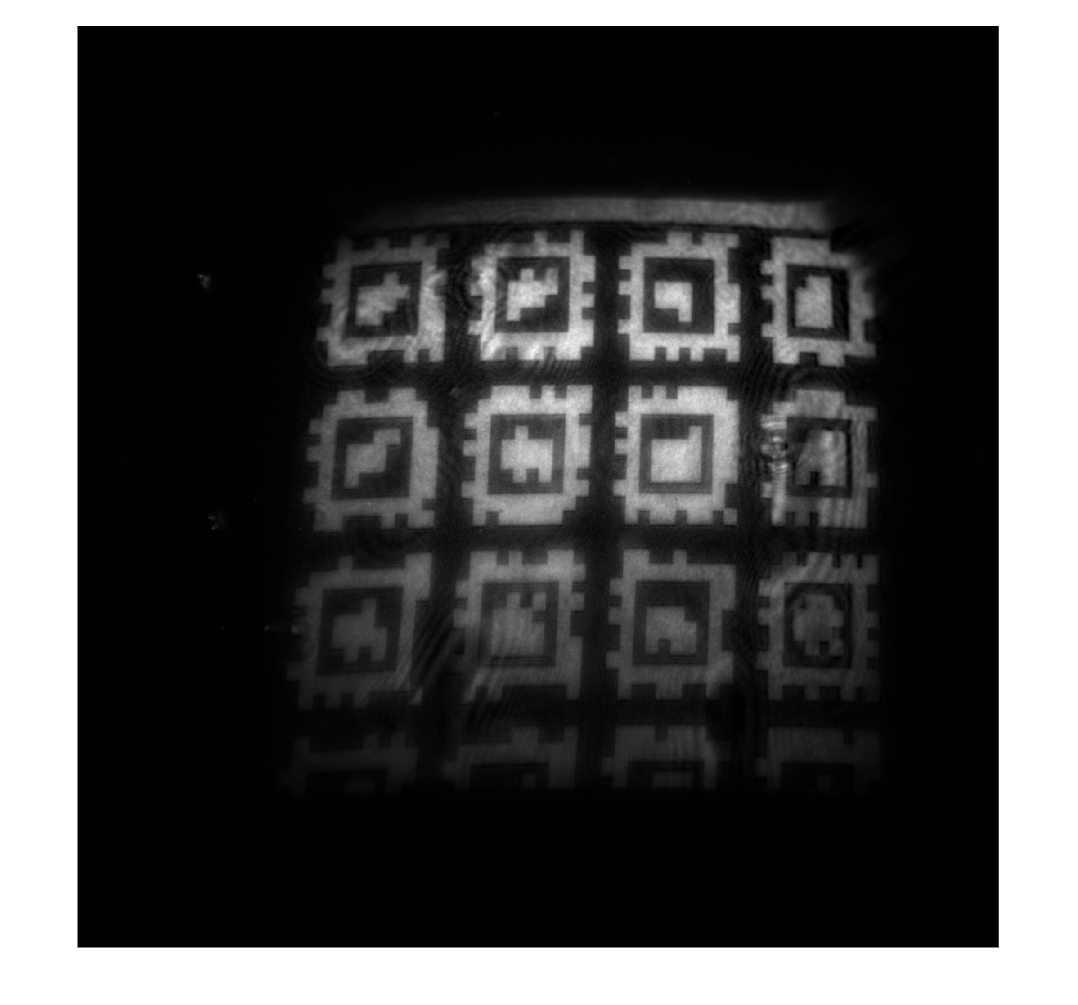

result = (mat2gray((white-cal)));
imshow(result);

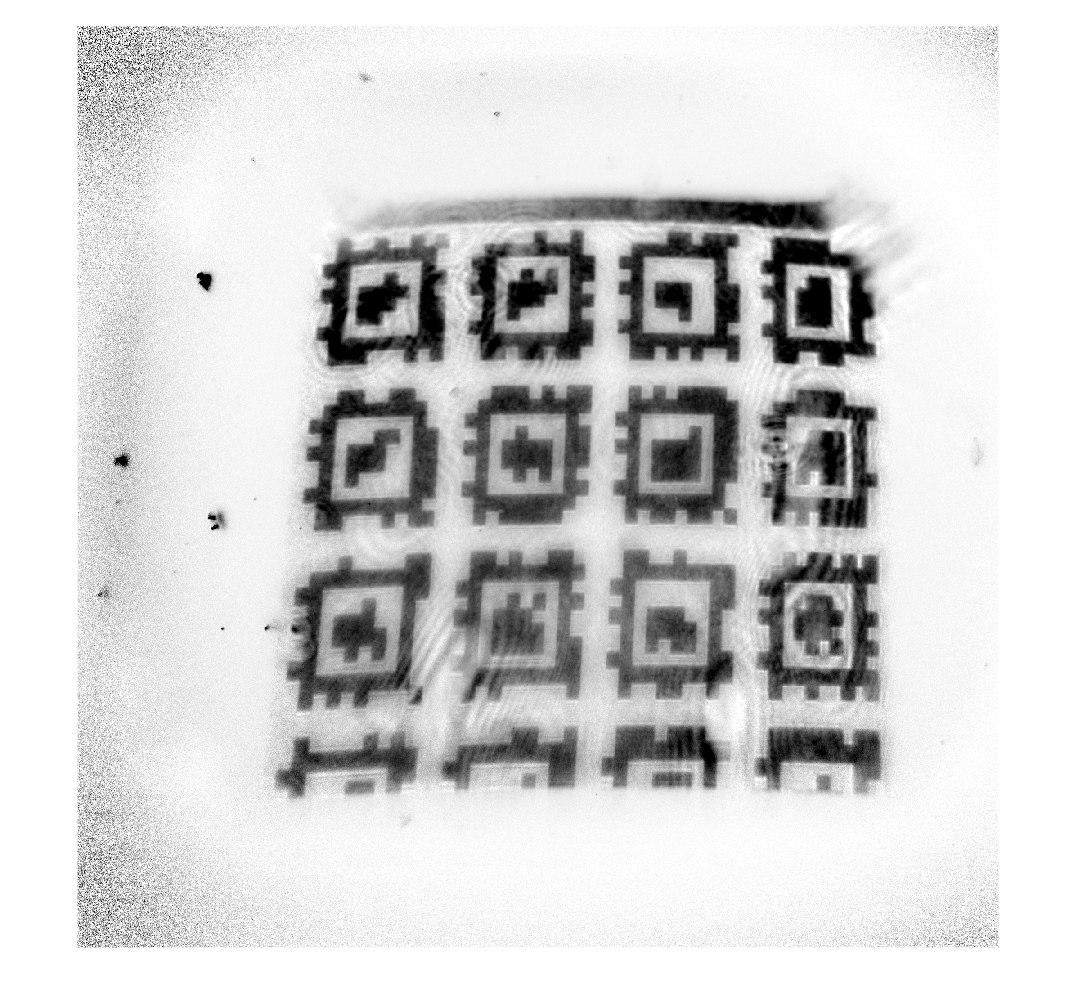

figure();
result = 1-imadjust(imflatfield(result,0.1*min(size(result))));
imshow(result);

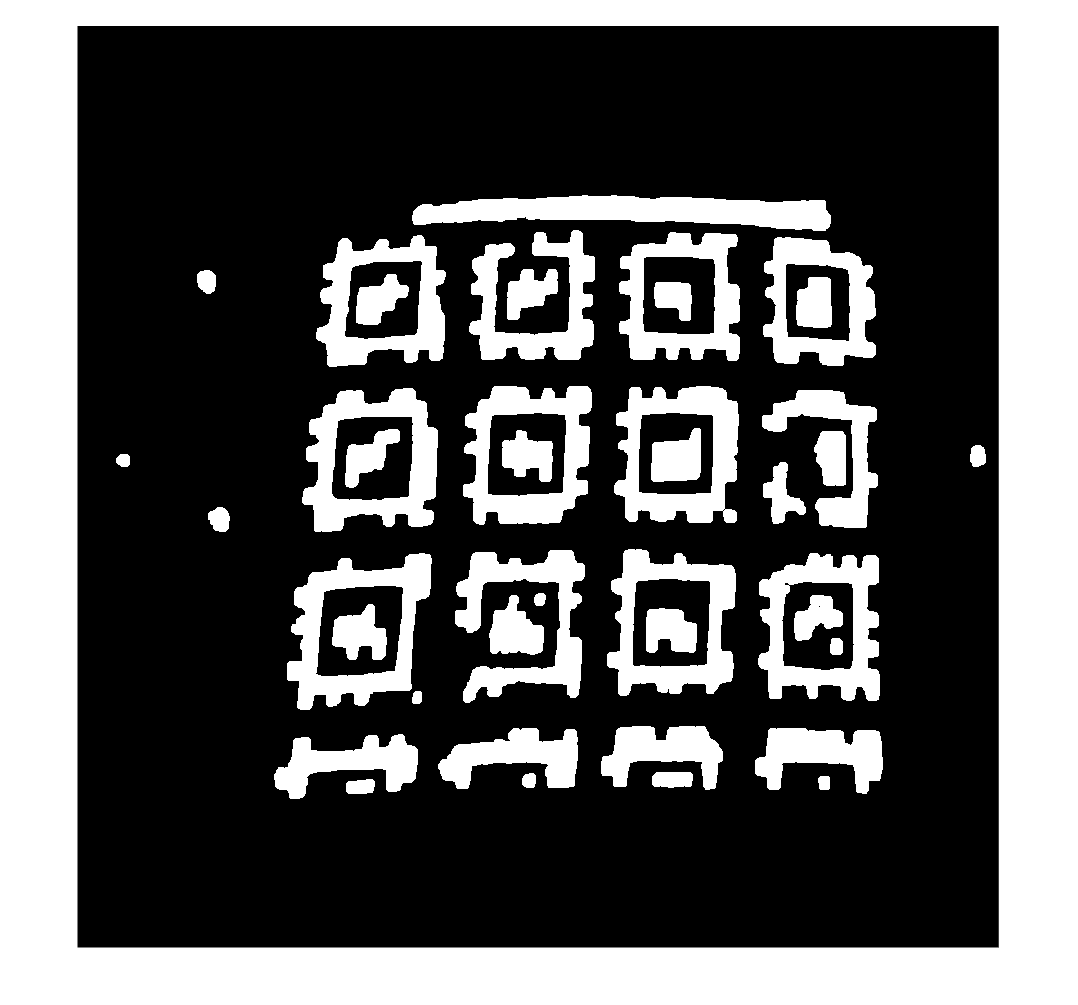

binIm = imbinarize(1-result,'adaptive');
binIm = imopen(binIm,strel('disk',10));
figure();
imshow(binIm);

[nonZeroRows,nonZeroColumns] = find(binIm);
topRow = min(nonZeroRows(:));
bottomRow = max(nonZeroRows(:));
leftColumn = min(nonZeroColumns);
rightColumn = max(nonZeroColumns);
cropped = result(topRow:bottomRow,leftColumn:rightColumn);


Read and localize the tags in the calibration pattern.

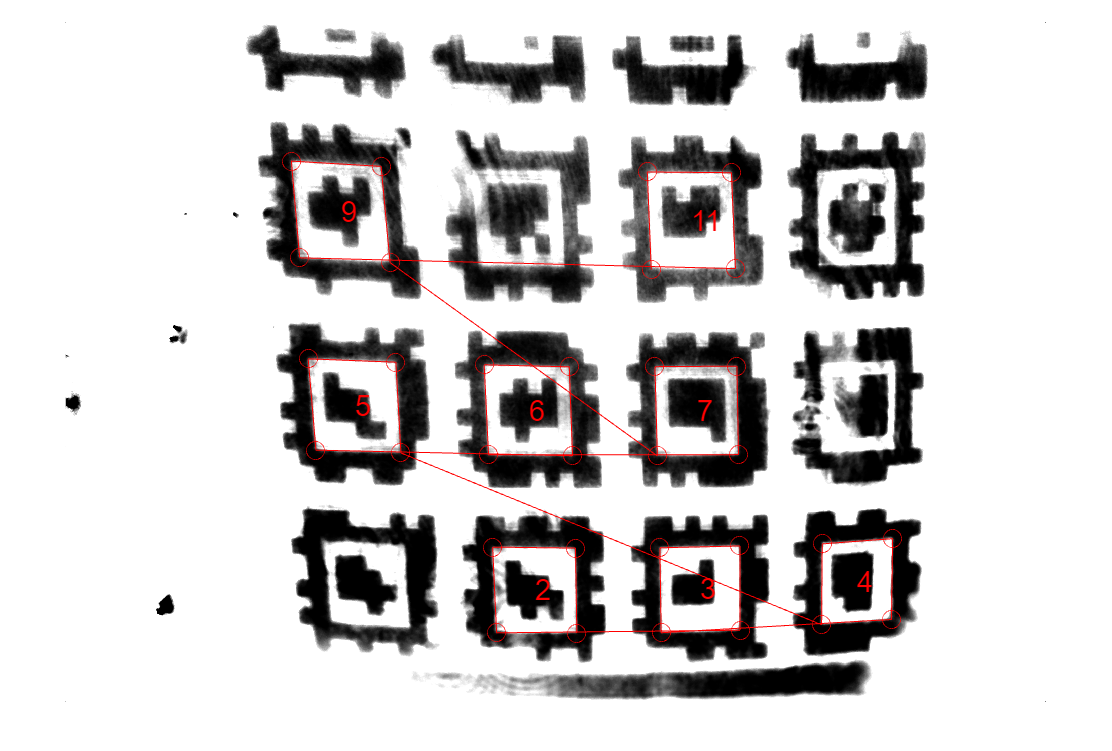

% figure();
% imhist(cropped);
% graythresh(cropped)
% croppedBin = imbinarize(cropped);
% final = imopen(croppedBin,strel("square",10));
% figure();
% tiledlayout('horizontal');
% nexttile();
% imshow(cropped);
% nexttile();
% imshow(croppedBin);
smoothed = medfilt2(cropped);
adj = imadjust(smoothed,[0.1,0.65],[],2);

final = adj;
[tagIds, tagLocs] = readAprilTag(final,tagFamily);
if isempty(tagIds)
    final = flip(final);
    [tagIds, tagLocs] = readAprilTag(final,tagFamily);
end

% Sort the tags based on their ID values.
[~, sortIdx] = sort(tagIds);
tagLocs = tagLocs(:,:,sortIdx);

% Reshape the tag corner locations into an M-by-2 array.
tagLocs_vec = reshape(permute(tagLocs,[1,3,2]),[],2);


% Display corner locations.
figure; imshow(final); hold on
plot(tagLocs_vec(:,1),tagLocs_vec(:,2),"ro-",MarkerSize=15)
for i = 1:numel(tagIds)
    center = mean(tagLocs(:,:,i));
    text(center(1),center(2),string(tagIds(i)),'FontSize',24,'Color','red');
end